# UAV Scenario Tutorial

Create a scenario to simulate unmanned aerial vechicle (UAV) flights between a set of buildings. The example demonstates updating the UAV pose in open-loop simulations. Use the UAV scenario to visualize the UAV flight and generate simulated point cloud sensor readings.

## Introduction

To test autonomous algorithms, a UAV scenario enables you to generate test cases and generate sensor data from the environment. You can specify obstacles in the workspace, provide trajectories of UAVs in global coordinates, and convert data between coordinate frames. The UAV scenario enables you to visualize this information in the reference frame of the environment.

## Create Scenario with Polygon Building Meshes

A `uavScenario` object is model consisting of a set of static obstacles and movable objects called platforms. Use `uavPlatform` objects to model fixed-wing UAVs, multirotors, and other objects within the scenario. This example builds a scenario consisting of a ground plane and 11 buildings as by extruded polygons. The polygon data for the buildings is loaded and used to add polygon meshes.

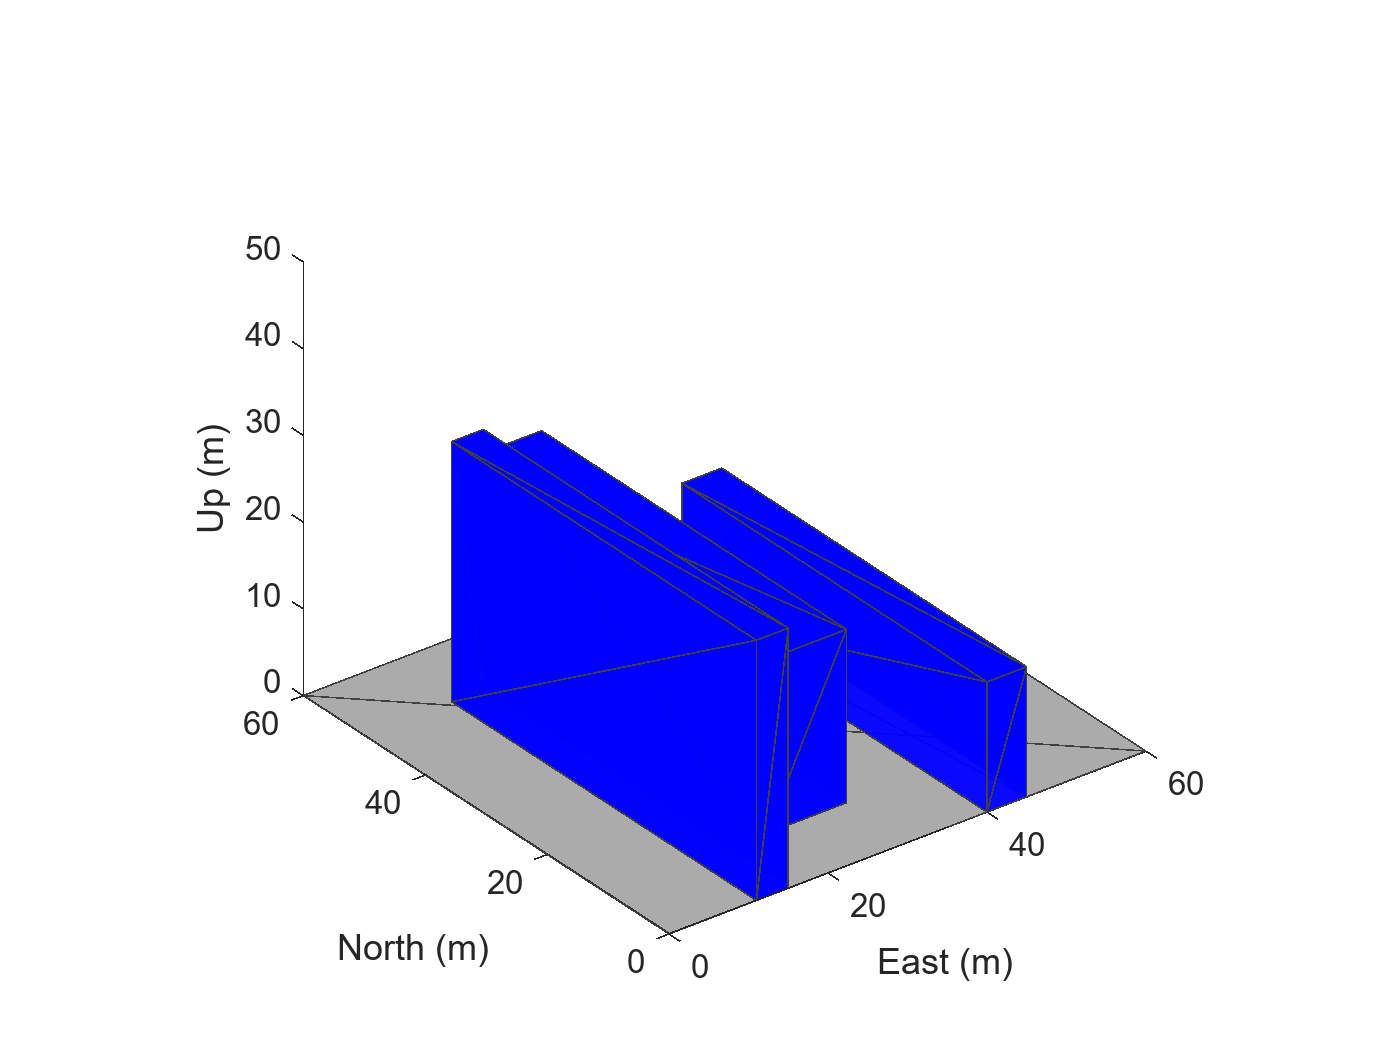

% Create the UAV scenario.
scene = uavScenario("UpdateRate",2);%,"ReferenceLocation",[75 -46 0]);

% Add a ground plane.
color.Gray = 0.651*ones(1,3);
color.Green = [0.3922 0.8314 0.0745];
color.Blue = [0 0 1];
color.Red = [1 0 0];
% addMesh(scene,"polygon",{[-250 -150; 200 -150; 200 180; -250 180],[-4 0]},color.Gray)
addMesh(scene,"polygon",{[0 0; 0 60; 60 60; 60 0],[-4 0]},color.Gray)  %{cornerPoints, [zMin, zMax]}, in meters

% Load building polygons.
load("buildingData.mat");

% a = [20, 25; 25, 25; 25, 30; 25 ,30] %random rect prism, for testing
raw_obs = readmatrix('3obs.txt');
obs = {};
for i=1:size(raw_obs, 1)
    obs{i} = [raw_obs(i,1) raw_obs(i,3); raw_obs(i,2) raw_obs(i,3); raw_obs(i,2) raw_obs(i,4); raw_obs(i,1) raw_obs(i,4)];
end

addMesh(scene,"polygon",{obs{1},[0 30]},color.Blue)
addMesh(scene,"polygon",{obs{2},[0 20]},color.Blue)
addMesh(scene,"polygon",{obs{3},[0 15]},color.Blue)

% Add sets of polygons as extruded meshes with varying heights from 10-30.
% addMesh(scene,"polygon",{a,[0 30]},color.Blue)
% addMesh(scene,"polygon",{buildingData{1}(1:4,:),[0 30]},color.Green)
% addMesh(scene,"polygon",{buildingData{2}(2:5,:),[0 30]},color.Green)
% addMesh(scene,"polygon",{buildingData{3}(2:10,:),[0 30]},color.Green)
% addMesh(scene,"polygon",{buildingData{4}(2:9,:),[0 30]},color.Green)
% addMesh(scene,"polygon",{buildingData{5}(1:end-1,:),[0 30]},color.Green)
% addMesh(scene,"polygon",{buildingData{6}(1:end-1,:),[0 15]},color.Green)
% addMesh(scene,"polygon",{buildingData{7}(1:end-1,:),[0 30]},color.Green)
% addMesh(scene,"polygon",{buildingData{8}(2:end-1,:),[0 10]},color.Green)
% addMesh(scene,"polygon",{buildingData{9}(1:end-1,:),[0 15]},color.Green)
% addMesh(scene,"polygon",{buildingData{10}(1:end-1,:),[0 30]},color.Green)
% addMesh(scene,"polygon",{buildingData{11}(1:end-2,:),[0 30]},color.Green)

% Show the scenario.
show3D(scene);
xlim([0 60])
ylim([0 60])
zlim([0 50])

% xlim([-250 200])
% ylim([-250 200])
% zlim([0 50])

## Define UAV Platform and Mount Sensor

You can define a `uavPlatform` in the scenario as a carrier of your sensor models and drive them through the scenario to collect simulated sensor data. You can associate the platform with various meshes, such as `fixedwing`, `quadrotor`, and `cuboid` meshes. You can define a custom mesh defined ones represented by vertices and faces. Specify the reference frame for describing the motion of your platform. 

Load flight data into the workspace and create a quadrotor platform using an NED reference frame. Specify the initial position and orientation based on loaded flight log data. The configuration of the UAV body frame orients the *x*-axis as forward-positive, the *y*-axis as right-positive, and the *z*-axis downward-positive.

load("flightData.mat")

path = readmatrix('3DRRTstar_25000itr_d88.txt');

path = transpose(path);
path = reshape(path, 1, size(path,1), size(path,2));

or = zeros(size(path));

% Set up platform
% plat = uavPlatform("UAV",scene,"ReferenceFrame","NED", ...
%     "InitialPosition",position(:,:,1),"InitialOrientation",eul2quat(orientation(:,:,1)));
%pos = %transpose(squeeze(path)) %only necessary if the input path isn't 3
%or = zeros(size(pos));
%pos = path;
%columns 
toa = 0:1:length(path)-1;
trj = waypointTrajectory("Waypoints", transpose(squeeze(path)), "TimeOfArrival", toa);
% Set up platform, now with included trajectory
plat = uavPlatform("UAV",scene,"ReferenceFrame","NED", ...
    "InitialPosition",path(:,:,1),"InitialOrientation",eul2quat(or(:,:,1)), "Trajectory", trj);
% plat = uavPlatform("UAV",scene,"ReferenceFrame","NED", ...
%     "InitialPosition",position(:,:,1),"InitialOrientation",eul2quat(orientation(:,:,1)), "Trajectory", traj);


% Set up platform mesh. Add a rotation to orient the mesh to the UAV body frame.
updateMesh(plat,"quadrotor",{10},color.Red,[0 0 0],eul2quat([0 0 pi]))

You can choose to mount different sensors, such as the `insSensor`, `gpsSensor`, or `uavLidarPointCloudGenerator` System objects to your UAV. Mount a lidar point cloud generator and a `uavSensor` object that contains the lidar sensor model. Specify a mounting location of the sensor that is relative to the UAV body frame.

lidarmodel = uavLidarPointCloudGenerator("AzimuthResolution",0.3324099,...
    "ElevationLimits",[-20 20],"ElevationResolution",1.25,...
    "MaxRange",90,"UpdateRate",2,"HasOrganizedOutput",true);

lidar = uavSensor("Lidar",plat,lidarmodel,"MountingLocation",[0,0,-1]);

## Fly the UAV Platform Along Pre-defined Trajectory and Collect Point Cloud Sensor Readings

Move the UAV along a pre-defined trajectory, and collect the lidar sensor readings along the way. This data could be used to test lidar-based mapping and localization algorithms. 

Preallocate the `traj` and `scatterPlot` line plots and then specify the plot-specific data sources. During the simulation of the `uavScenario`, use the provided `plotFrames` output from the scene as the parent axes to visualize your sensor data in the correct coordinate frames.

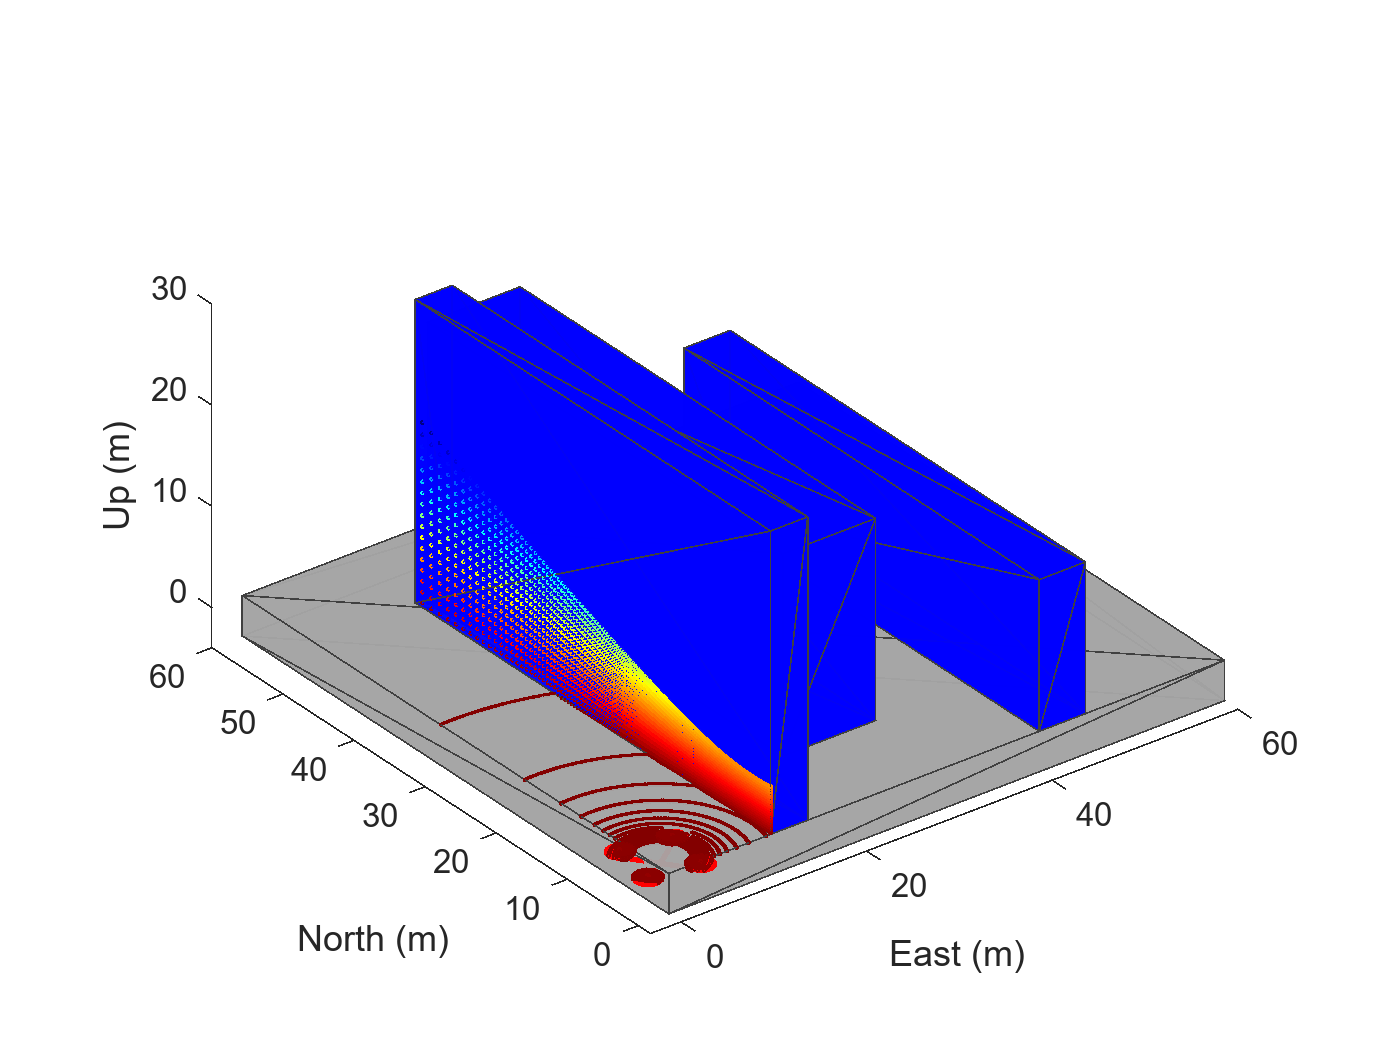

% Visualize the scene
[ax,plotFrames] = show3D(scene);

% Update plot view for better visibility.
xlim([0 60])
ylim([0 60])
% xlim([-250 200])
% ylim([-150 180])
zlim([0 50])
view([-110 30])
axis equal
hold on

% Create a line plot for the trajectory.
traj = plot3(trj.Waypoints(:,1),trj.Waypoints(:,2),trj.Waypoints(:,3),"Color","green","LineWidth",2);
traj.XDataSource = "path(:,1,1:idx+1)";
traj.YDataSource = "path(:,2,1:idx+1)";
traj.ZDataSource = "path(:,3,1:idx+1)";

% Create a scatter plot for the point cloud.
colormap("jet")
pt = pointCloud(nan(1,1,3));
scatterplot = scatter3(nan,nan,nan,1,[0.3020 0.7451 0.9333],...
                       "Parent",plotFrames.UAV.Lidar);
scatterplot.XDataSource = "reshape(pt.Location(:,:,1),[],1)";
scatterplot.YDataSource = "reshape(pt.Location(:,:,2),[],1)";
scatterplot.ZDataSource = "reshape(pt.Location(:,:,3),[],1)";
scatterplot.CDataSource = "reshape(pt.Location(:,:,3),[],1) - min(reshape(pt.Location(:,:,3),[],1))";

% Start Simulation
setup(scene)
for idx = 0:size(path, 1)-1
    [isupdated,lidarSampleTime, pt] = read(lidar);
    if isupdated
        % Use fast update to move platform visualization frames.
        show3D(scene,"Parent",ax); % removing FastUpdate shows the UAV trajectory
        %show3D(scene,"Time",lidarSampleTime,"FastUpdate",true,"Parent",ax);
        % Refresh all plot data and visualize.
        refreshdata
        drawnow limitrate
    end
    % Advance scene simulation time and move platform.
    advance(scene);
    move(plat,[path(:,:,idx+1),zeros(1,6),eul2quat(or(:,:,idx+1)),zeros(1,3)])
    % Update all sensors in the scene.
    updateSensors(scene)
end
hold off

*Copyright 2020 The MathWorks, Inc.*